## Programmierblatt 1

Jonathan Schnitzler

Matr. - Nr: 3465192

Wir betrachten hier verschiedene Verfahren, um Differentialgleichungen zu lösen (Aufgabe 1) und gehen dann über diese Methoden auf Leib und Seele zu testen.

### Aufgabe 1

Die Funktionen sind in einem jeweiligen script geschrieben.

### Aufgabe 2 (Räuber-Beute Modell)

%Parameter in struct p
p.alpha = 1;
p.beta = 1;
p.gamma = 1;
p.delta = 1;

%startvalue
y_0 = [0.5;0.5];

%total time
T = 20;

%step size
tau = [0.64, 0.32, 0.16, 0.08, 0.04]

tau =     0.6400    0.3200    0.1600    0.0800    0.0400


tau = [0.05, 0.025];
%function handle
f =  @lotkaVolterra

f = function_handle with value:
    @lotkaVolterra


Plotten wir zunächst das Phasendiagramm der Lotka-Volterra Gleichung

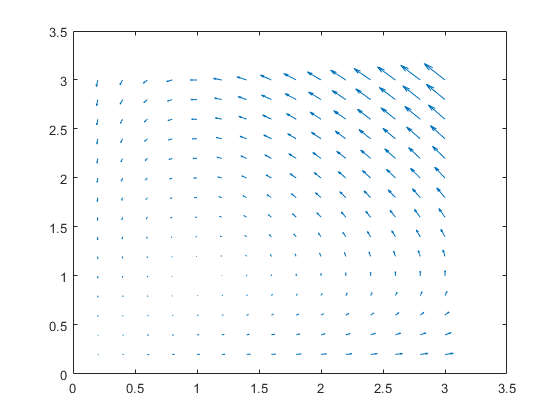

fig = figure;
nElem = 16;
meshX = linspace(0,3,nElem);
meshY = linspace(0,3,nElem);
[X,Y] = meshgrid(meshX,meshY);
U = zeros(nElem,nElem);
V = zeros(nElem,nElem);
for k = 1:nElem
    for l = 1:nElem
        foo = f(p, 0, [meshX(k),meshY(l)]);
        U(k,l) = -foo(2); %Verstehe ich nicht
        V(k,l) = -foo(1);
    end
end
quiver(X,Y,U,V);


%Refactored this code into a function since we want to use it again
figEuler = createQuiver(f, p);
hold on

Nun testen wir die in **Aufgabe 1** implementierten Verfahren

`explicit_euler:`

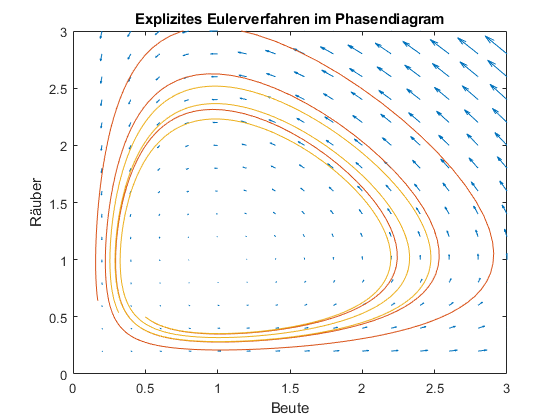

figPopuEul = figure;
hold on
for k = tau
    Y_euler = explicit_euler(f,y_0,T,k,p);
    
    figure(figEuler);
    plot(Y_euler(1,:),Y_euler(2,:));
    
    figure(figPopuEul);
    t = 0:k:T;
    plot(t,Y_euler(1,:),t,Y_euler(2,:))
end

figure(figEuler)
title('Explizites Eulerverfahren im Phasendiagram')
xlabel('Beute')
ylabel('Räuber')
xlim([0 3])
ylim([0 3])

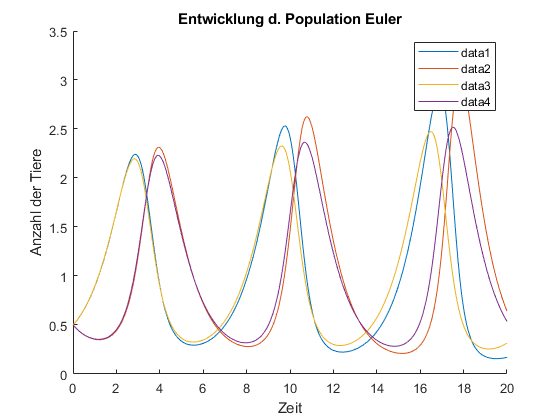


figure(figPopuEul)
title('Entwicklung d. Population Euler')
xlabel('Zeit')
ylabel('Anzahl der Tiere')
legend()

`explicit_heun:`

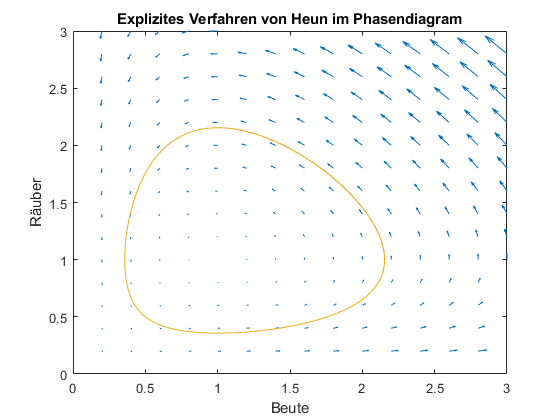

figHeun = createQuiver(f, p);
hold on
figPopH = figure;
hold on
for k = tau
    Y_heun = explicit_heun(f,y_0,T,k,p);
    
    
    figure(figHeun)
    plot(Y_heun(1,:),Y_heun(2,:));
    
    figure(figPopH)
    t = 0:k:T;
    plot(t,Y_heun(1,:),t,Y_heun(2,:))
end
figure(figHeun)
title('Explizites Verfahren von Heun im Phasendiagram')
xlabel('Beute')
ylabel('Räuber')
xlim([0 3])
ylim([0 3])

hold off

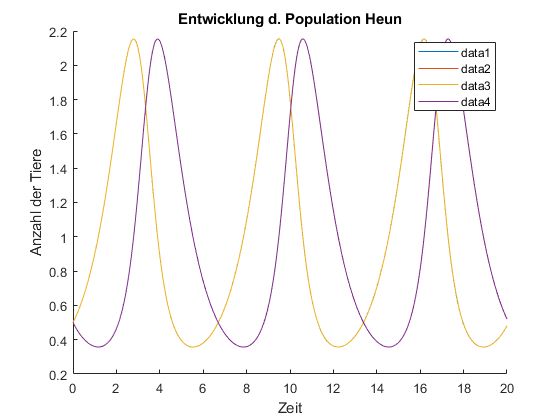

figure(figPopH)
title('Entwicklung d. Population Heun')
xlabel('Zeit')
ylabel('Anzahl der Tiere')
legend()
hold off

c) Fazit

### Aufgabe 3

%parameter
pL.alpha = 10;
pL.beta = 1/10;
pL.xi = pL.alpha/pL.beta;
pL.t_0 = 0;
pL.p_0 = 1; %MISSING VALUE

T = 1;
tauSize = [1 9];
tau = zeros(tauSize);
for k = 0:tauSize(2)-1
    tau(k+1) = 1/80 * 2^(-k);
end

logisticFun = @(pL, t, pIn) pL.alpha .* pIn - pL.beta .* (pIn.^2);

Nun möchten wir den Fehler zu der analytischen Rechnung betrachten

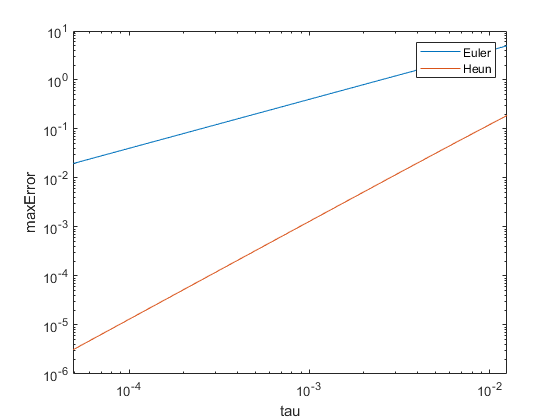

maxErrEul = zeros(tauSize);
maxErrHeun = zeros(tauSize);
maxErrEul = zeros(tauSize);
tCpuEul = zeros(tauSize);
tCpuHeun = zeros(tauSize);
tCpuRK = zeros(tauSize);

for k = 1:tauSize(2)
    figure
    t = 0:tau(k):T;
    anaSol = logisticSol(pL,t);
    tic
    EulSol = explicit_euler(logisticFun,pL.p_0,T,tau(k),pL);
    tCpuEul(k) = toc;
    tic
    HeunSol = explicit_heun(logisticFun,pL.p_0,T,tau(k),pL);
    tCpuHeun(k) = toc;
%     plot(t,anaSol, t,EulSol, t, HeunSol)
%     xlim([0 1])
%     ylim([0 100])
    
    
    
    errorEul = abs(anaSol-EulSol);
    errorHeun = abs(anaSol-HeunSol);
    
    
    %Aufgabe a
    maxErrEul(k) = max(errorEul);
    maxErrHeun(k) =max(errorHeun);
    %Aufgabe b
%     figure
%     plot(t, errorEul, t, errorHeun);
%     title('Fehler')
end
loglog(tau, maxErrEul, tau, maxErrHeun)
ylabel('maxError')
xlabel('tau')
legend('Euler','Heun')

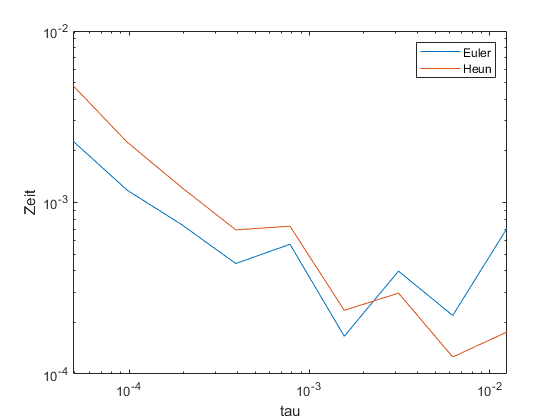


loglog(tau, tCpuEul, tau, tCpuHeun)
ylabel('Zeit')
xlabel('tau')
legend('Euler','Heun')